# Classifying Urban sounds using Machine Learning and Deep Learning

## 2 Data Preprocessing and Data Splitting

Audio properties that will require normalising

Following on from the previous notebook, we identifed the following audio properties that need preprocessing to ensure consistency across the whole dataset:

- Audio Channels

- Sample rate

- Bit-depth

We will continue to use Signal Processing Toolbox which will be useful for the pre-processing and feature extraction.

## **Sample rate conversion**

There is a wide range of Sample rates that have been used across all the samples which is a concern (ranging from 96k to 8k).

This likley means that we will have to apply a sample-rate conversion technique (either up-conversion or down-conversion) so we can see an agnostic representation of their waveform which will allow us to do a fair comparison

## Bit-depth

I resample the audio Wav. file to 16 bits. This removes the complication of the dataset having a wide range of bit-depths.

## **Merge audio channels**

We will also convert the signal to mono, meaning the number of channels will always be 1.

[It will take up to 30min for running, please be patient.]

%TODO Up convert or down convert
%From the information in the previous steps choose which what would you do?

for i=1:1:length(ads.Files)
    y =audioread(ads.Files{i});
    if size(y,2) == 1
        result = y;
    else
        result = (y(:,1)+y(:,2))/2;
    end
    audiowrite(ads.Files{i},result,44100,'BitsPerSample',16);
    clear y Fs result
end

## **Let visualize and listen to the data again**

It is to ensure our data does not distorted much from original Wav.file. Play few round to have observe the plot and sound.

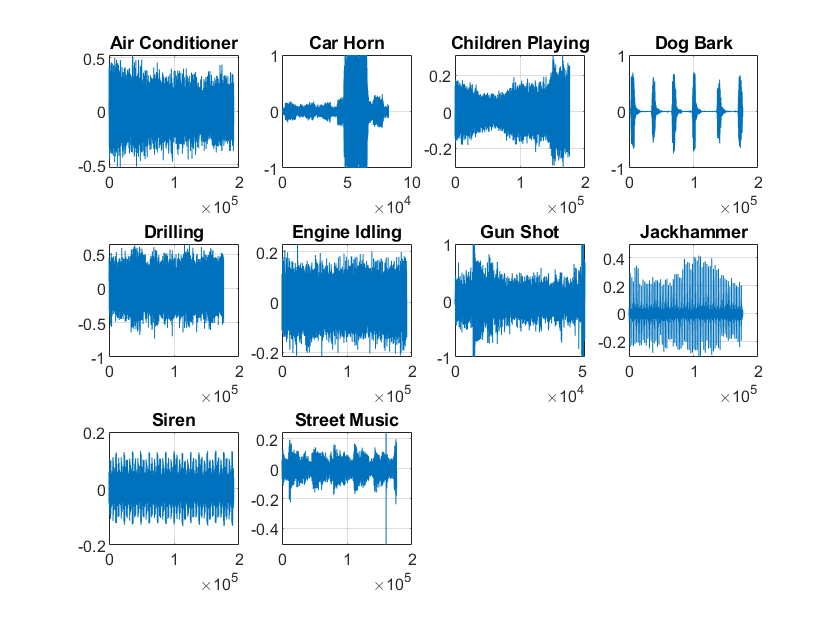

figure()
datafolder = "UrbanSound8K/structure";
currentfolder = pwd;
cd(datafolder);
listdir=dir;  
for i=3:1:length(listdir)
    cd(listdir(i).name)
    inside=dir;
    subplot(3,4,i-2);
    [y,fs]=audioread(inside(randi([4,100])).name);
    plot(y(:,:)); 
    soundsc(y(:,:),fs);
    grid on;
    title(listdir(i).name)
    drawnow;
    pause(2)
    cd(strcat(currentfolder,'\',datafolder));
end

cd(currentfolder);

Observation : if you look at the plot above, you will notice some are looking similar to each other although you still can differentiate it through sound. Especially, gun shot is looking smilar to jackhammer. Drilling and Engine Idling are also looking similar.Now we take note of this first, it might be useful information for us to increase the accuracy of model; 

## Extract Features - Machine Learning Using DiagnosticFeatureDesigner 

Restructure the data to table form - data type accepted by Diagnostic Feature Designer

datafolder = "UrbanSound8K/structure";

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');

for i=1:1:length(ads.Files)
    y =audioread(ads.Files{i});
    signal{i}=y;
    labels(i)= ads.Labels(i);
end

tablefordiagnostic = table(signal',labels');
tablefordiagnostic.Properties.VariableNames{1} = 'Signal';
tablefordiagnostic.Properties.VariableNames{2} = 'Label';
head(tablefordiagnostic)

ans = 8×2 table
         Signal               Label     
    _________________    _______________

    {176400×1 double}    Air Conditioner
    {176400×1 double}    Air Conditioner
    {176400×1 double}    Air Conditioner
    {176400×1 double}    Air Conditioner
    {176400×1 double}    Air Conditioner
    {176400×1 double}    Air Conditioner
    {176400×1 double}    Air Conditioner
    {176400×1 double}    Air Conditioner


diagnosticFeatureDesigner

After opening the app, please follows the steps below:

1) Import Data into App

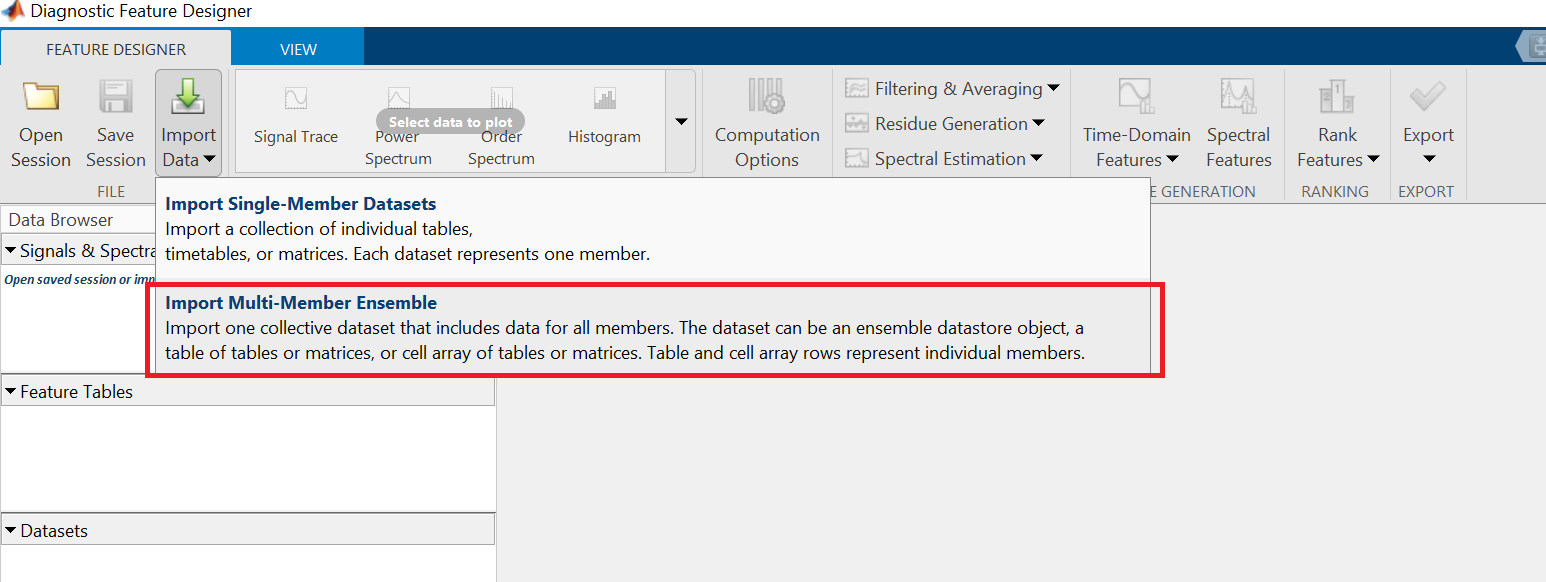

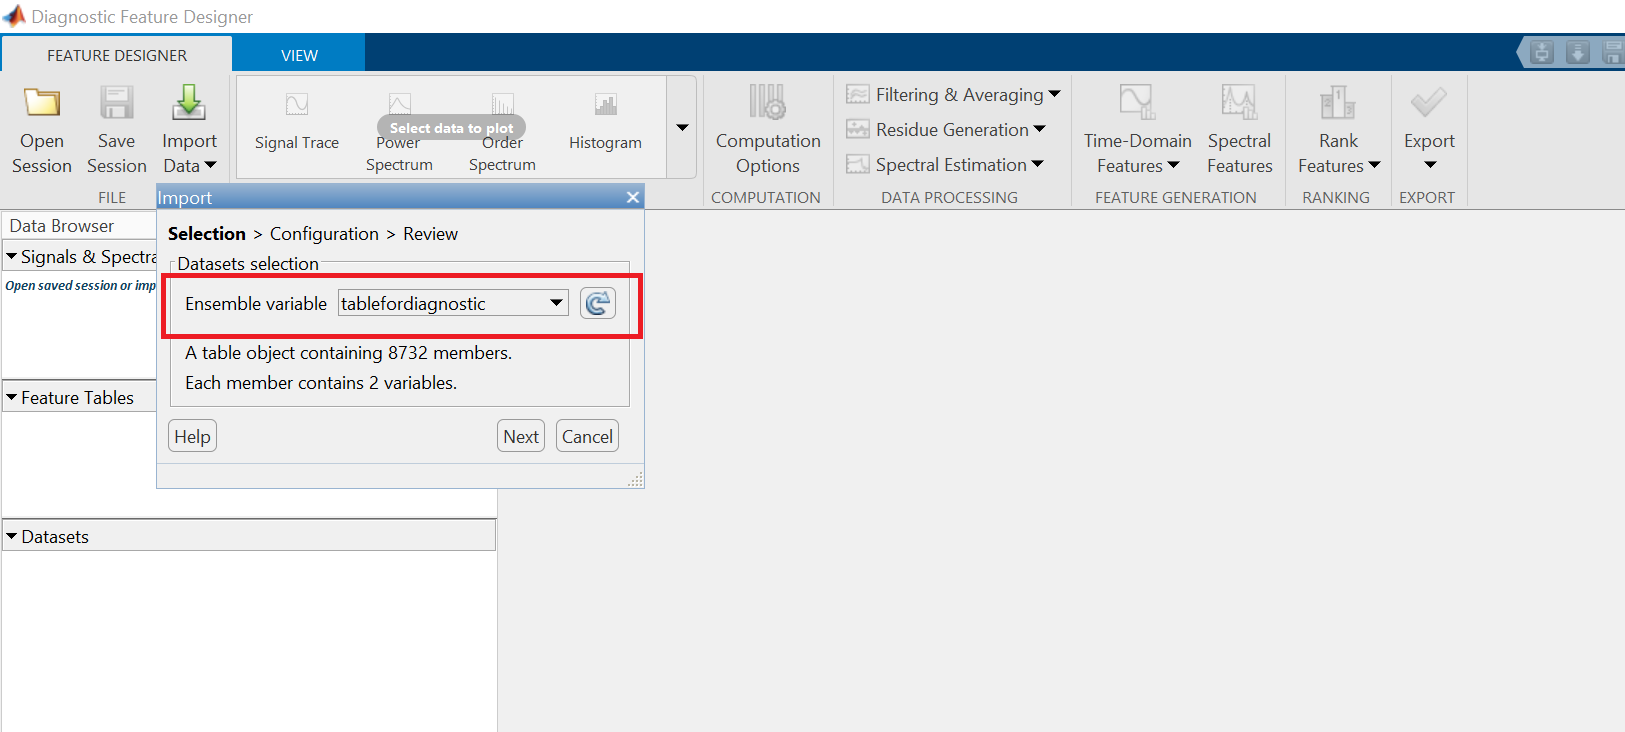

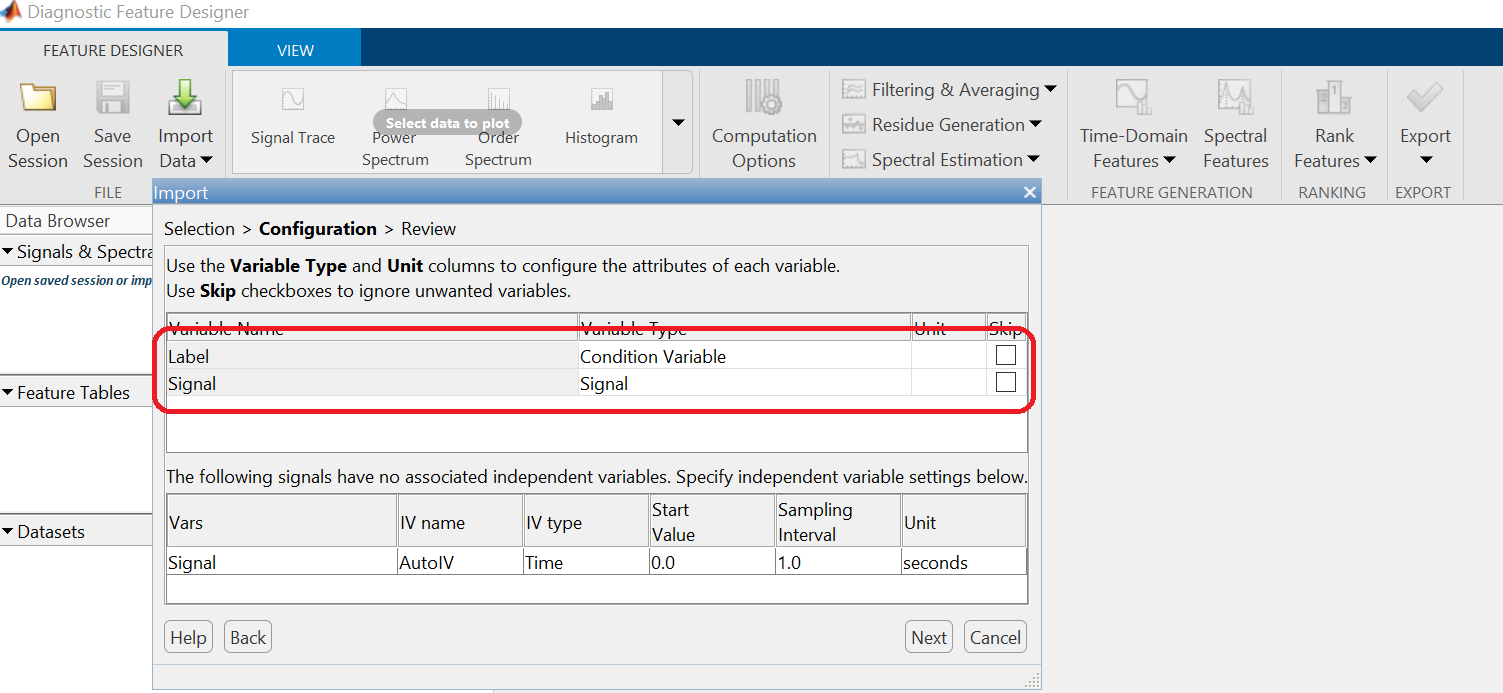

2) Extract Signal Features

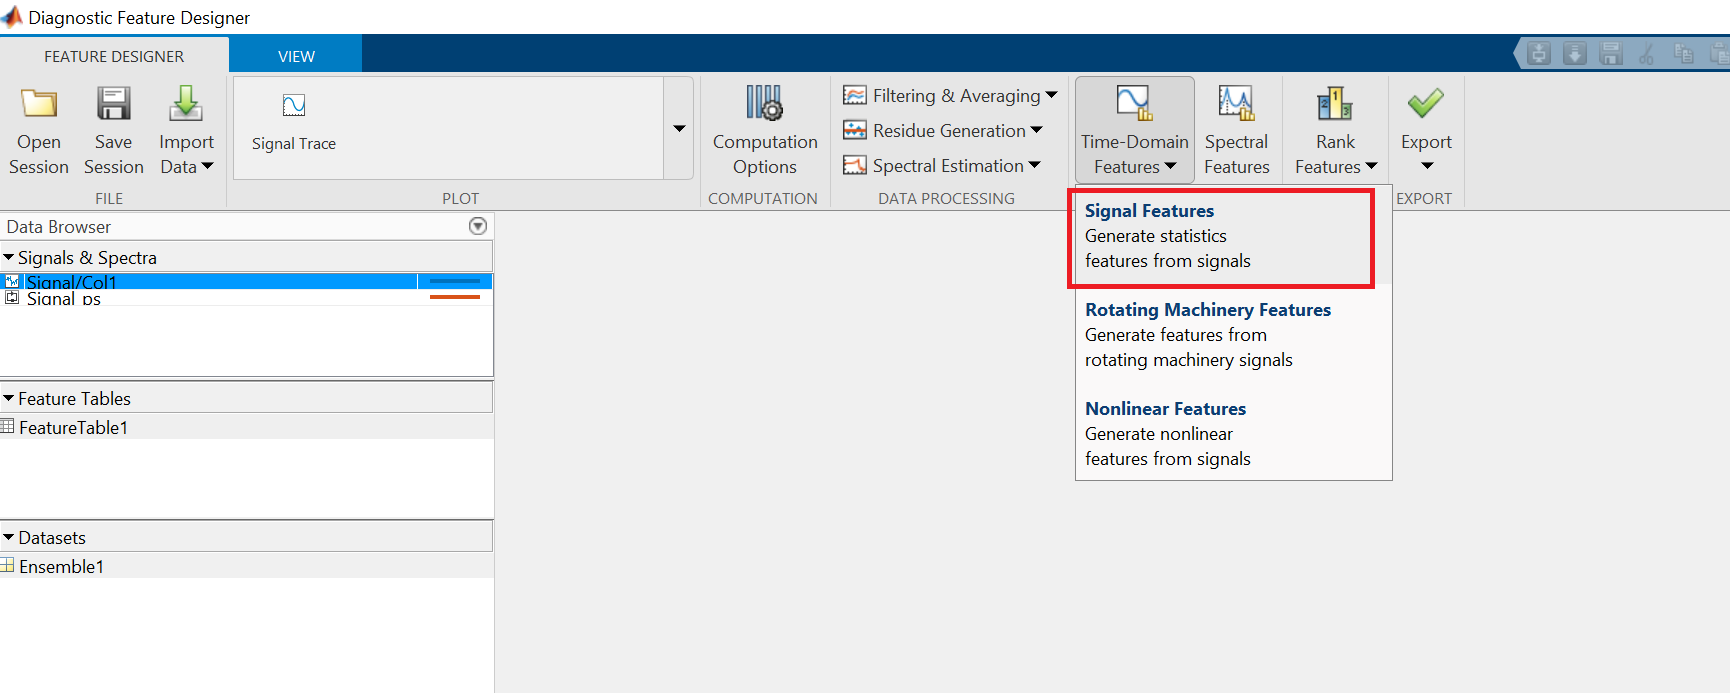

Convert to Power Specturm to extract Spectral Features.

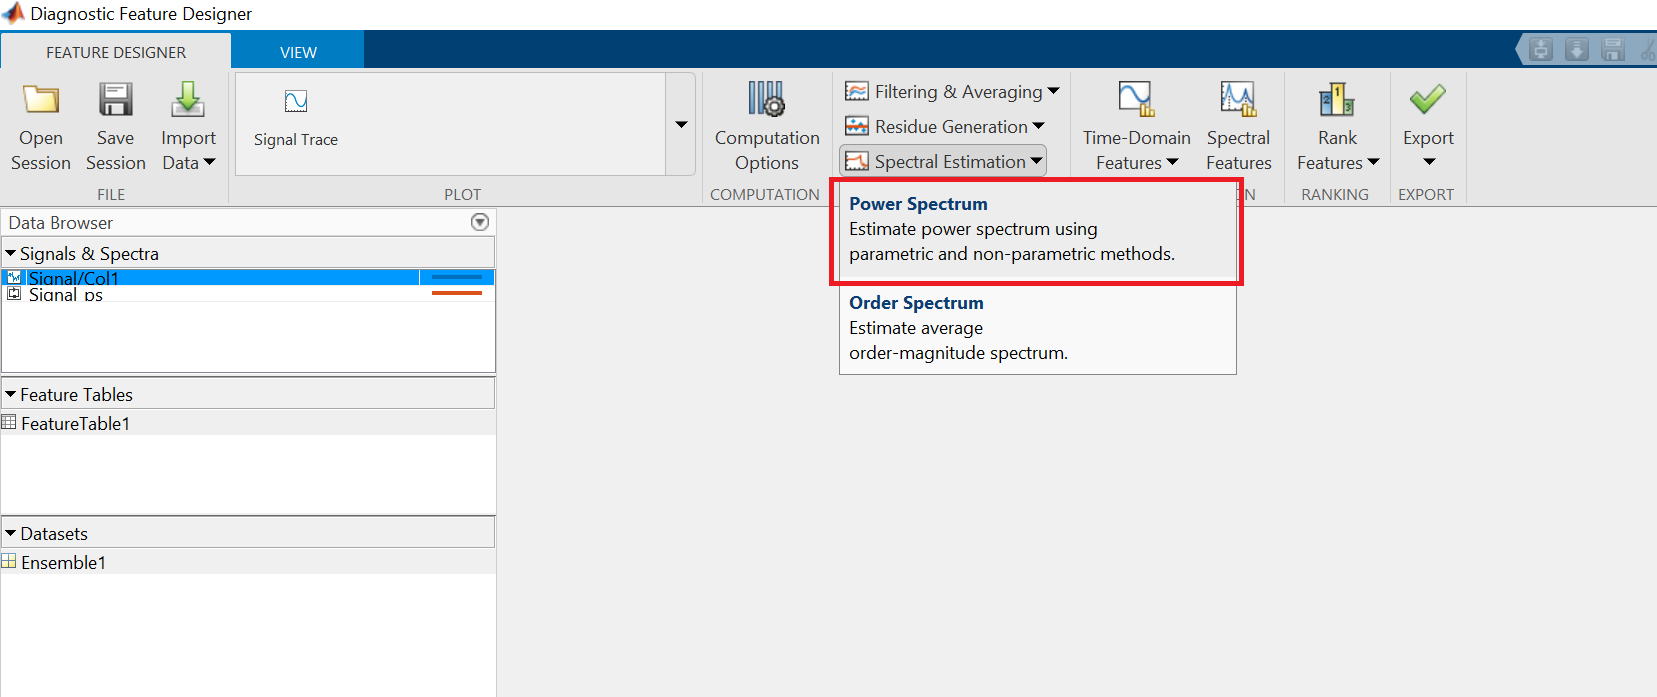

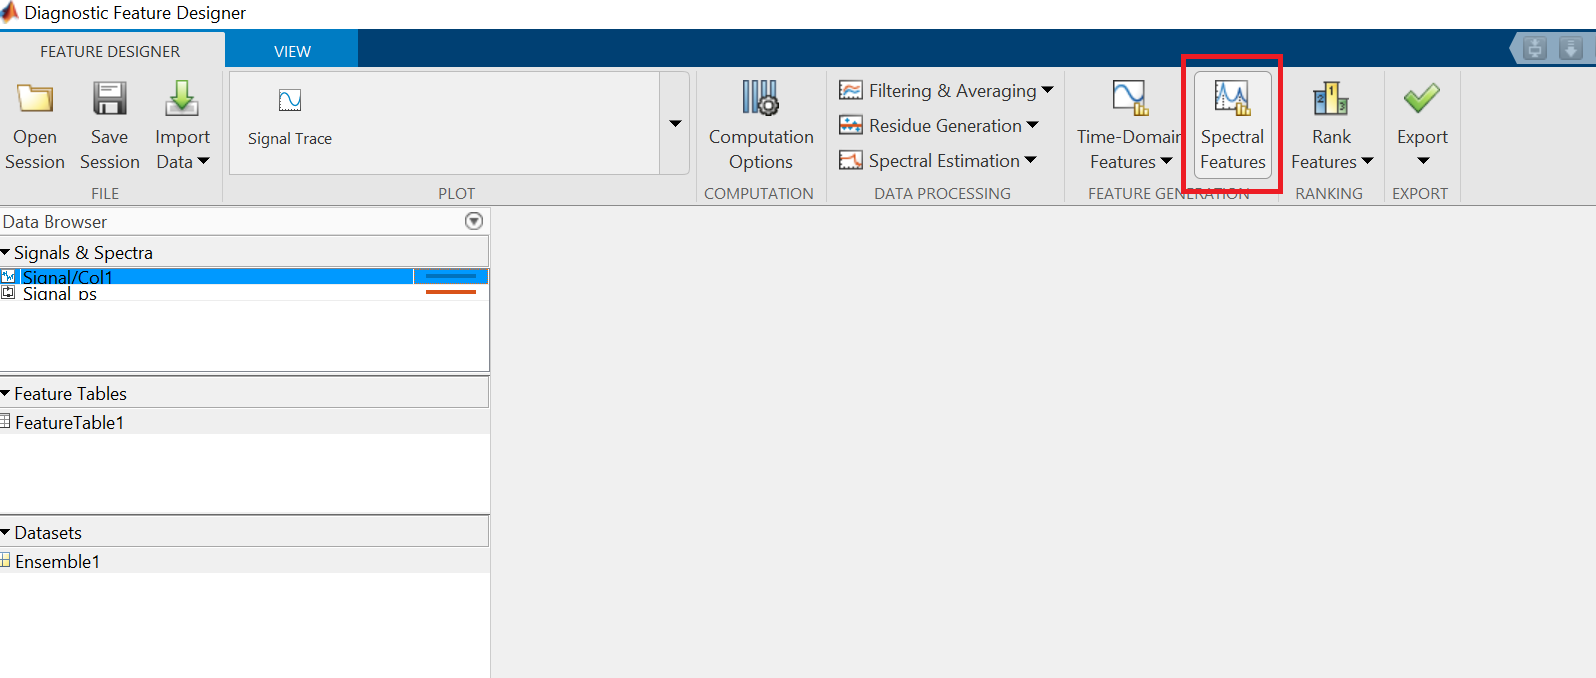

3) Now, the time-domain features and spectral features are stored in the FeatureTable1.

Rank the features with ANOVA, and select the top few features, it will help to get higher accuracy with shorter training time later.

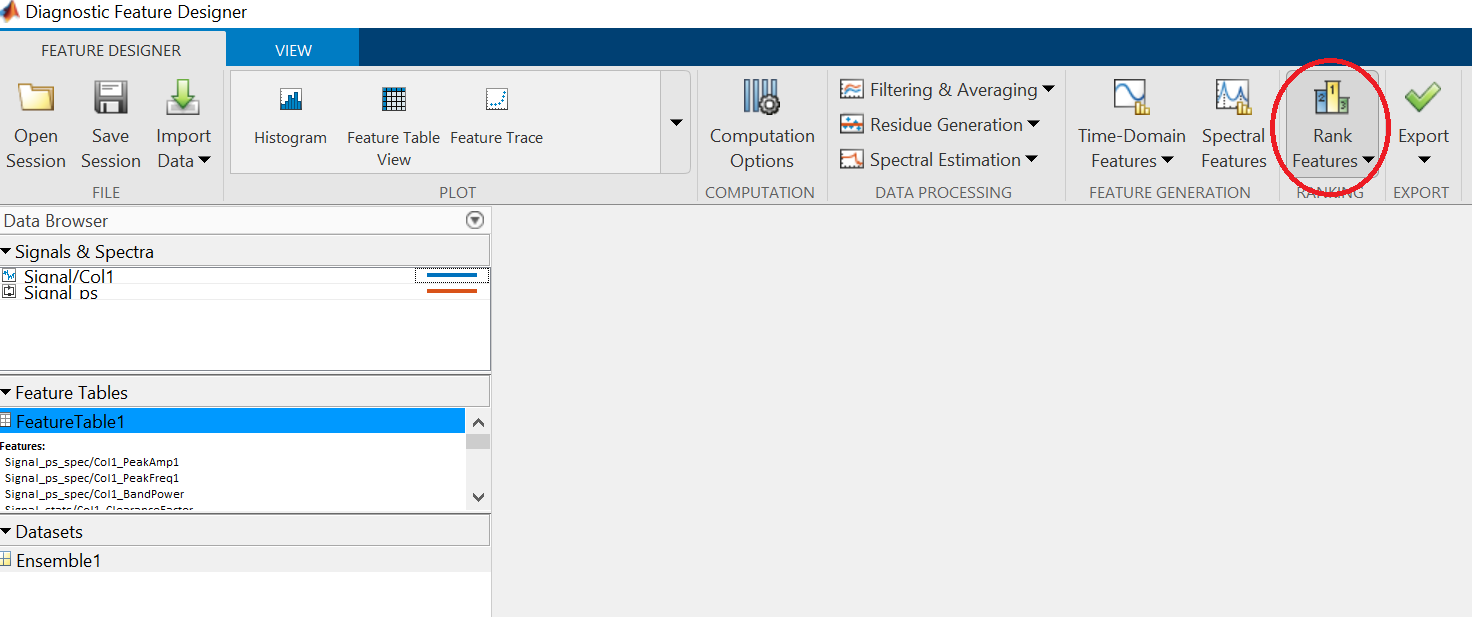

Result of rank features (using one-way ANOVA)

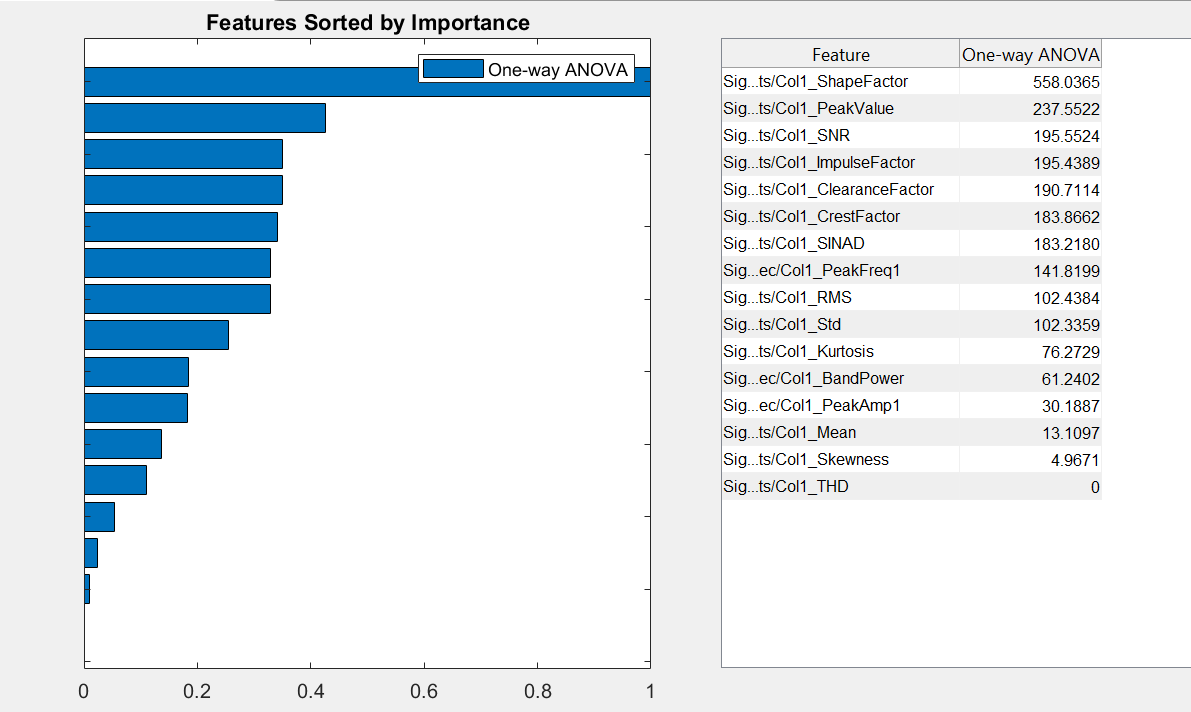

from the result above, we can notice that spectral features (Peak Frequency, Peak Amplitude, Band Power are not playing important role). However, other than one-way ANOVA, let try to rank the features using Kruskal-Wallis:

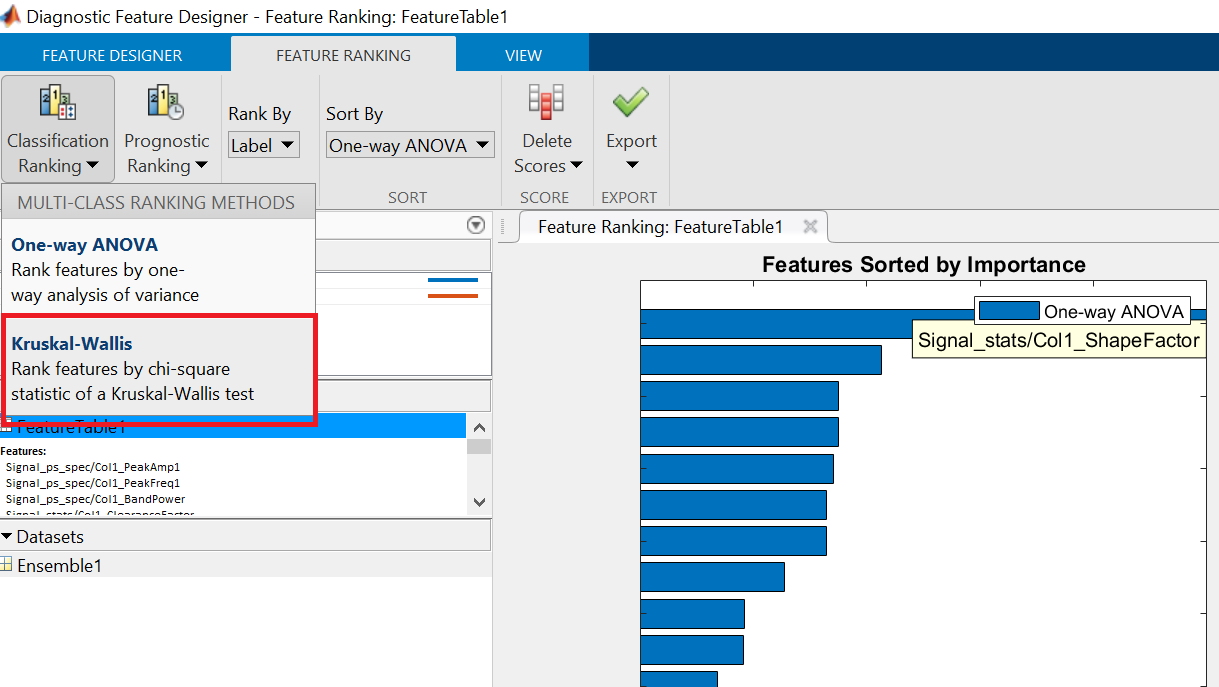

Result of rank features (using Kruskal-Wallis):

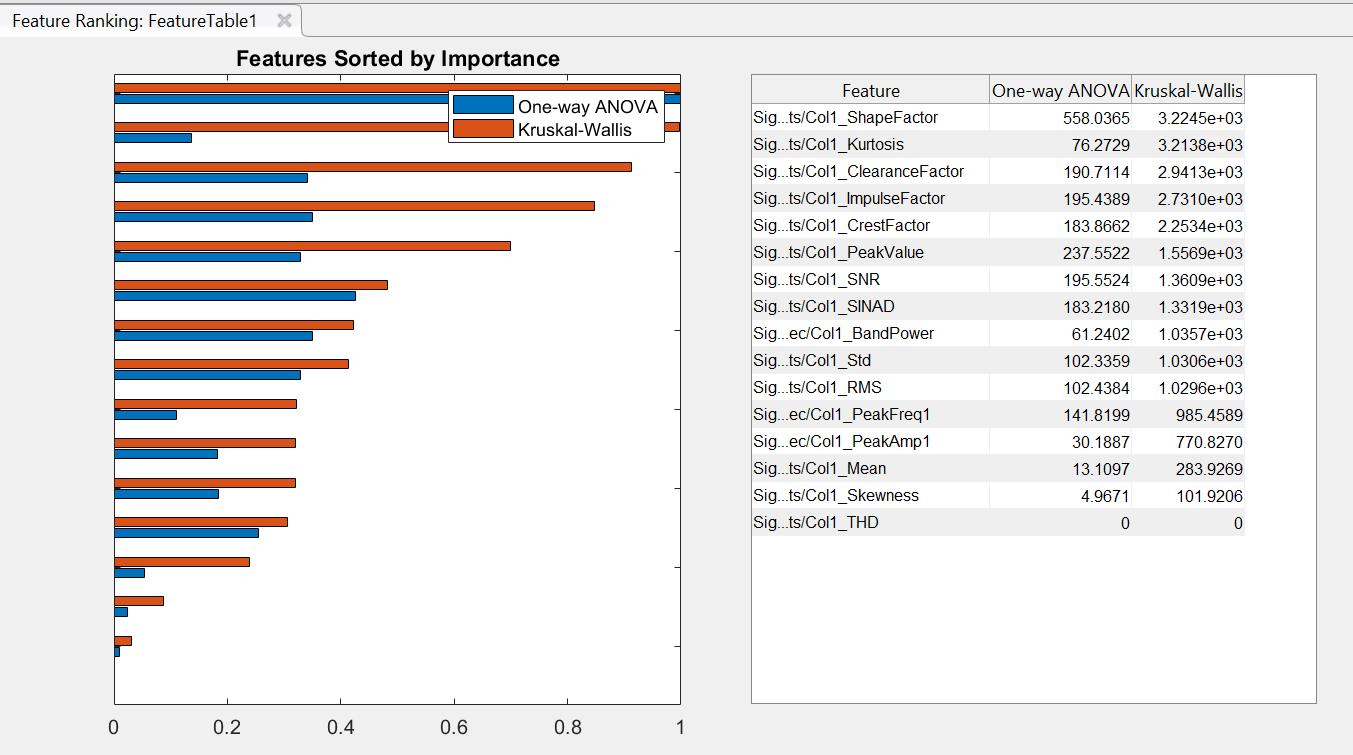

It is interesting that we get different result from Kruskal-Wallis, however, spectral features (Peak Frequency, Peak Amplitude, Band Power) ramains not important (Not in the top 8).

Total is 16 features, in fact, you may consider to throw all features into machine learning to train, after training, some model (eg. decision tree) will tell you what features are important to them. Other than this, you may use bayesian optimization to optimize the selection of features in machine learning training. 

No worries, once we start training the model in regression learner app, then you will have clearer picture.

Here, I will only remove the last 3 time-domain features (Mean, Skewness,THD), all the spectral features will be remained in the table for training.

3) Export the selected features to workspace for visualization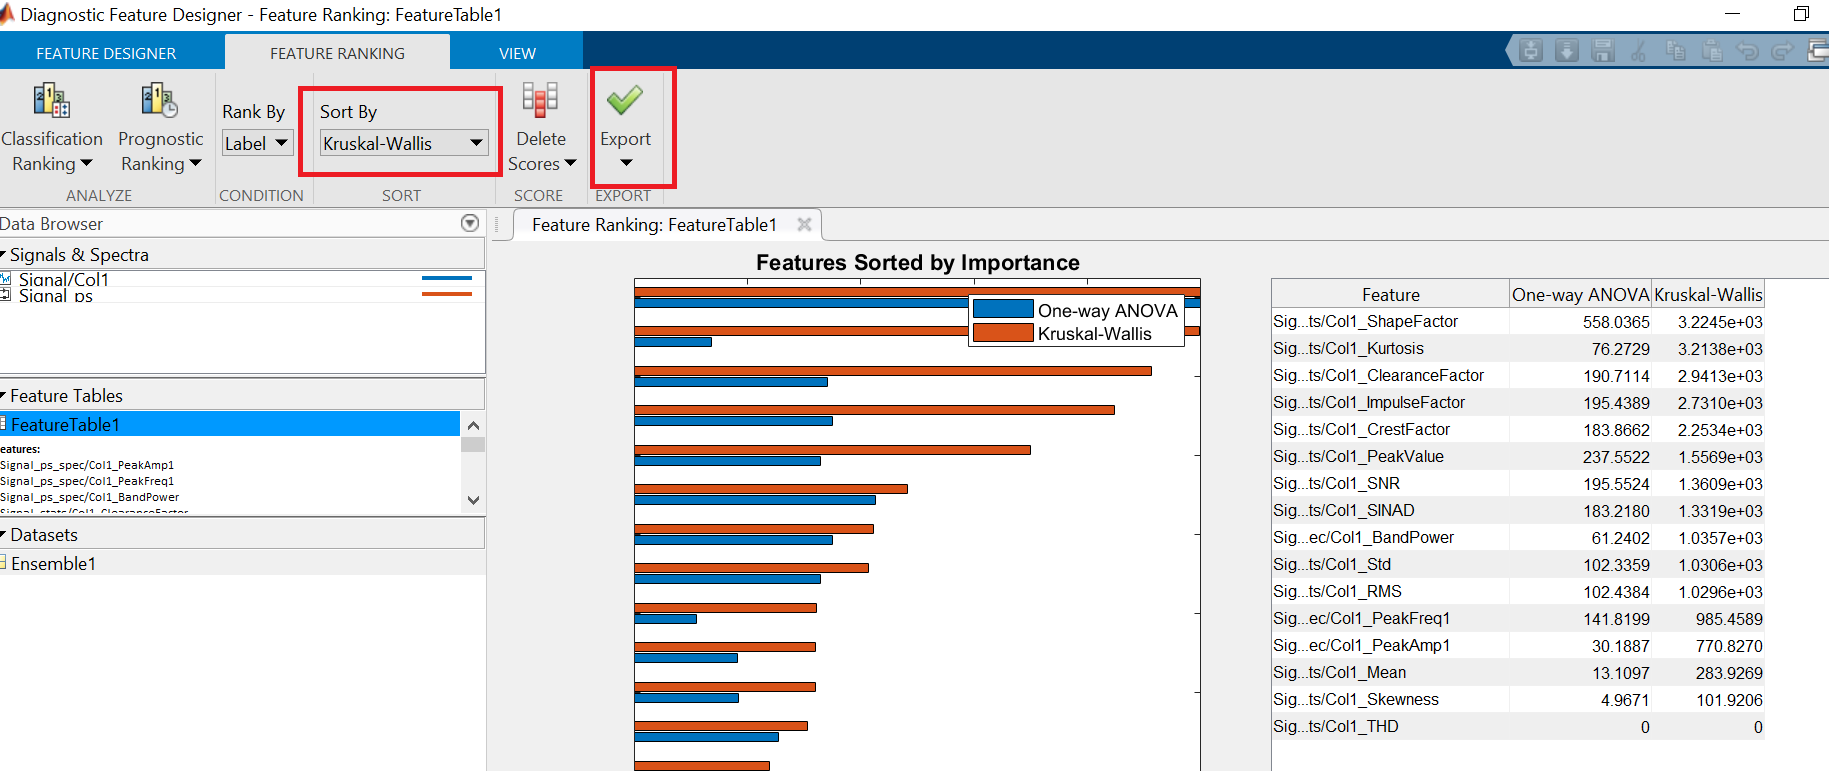

It is always encouraged to visualize the data first before training, sometimes, the visualization will give you some insight how to increase the acuracy. 

## Feature Engineering and Visualizations

Feature Selection, we have completed it in the diagnostic feature designer. 

[https://www.mathworks.com/help/stats/dimensionality-reduction.html](https://www.mathworks.com/help/stats/dimensionality-reduction.html)

Feature Visualization

Plot the Principal Components (PCA) and color by Category

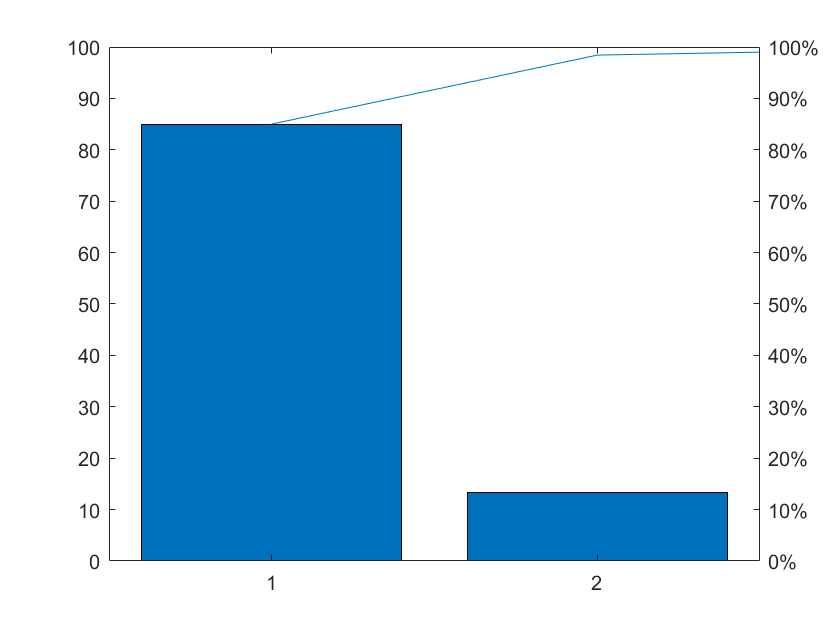

[coeff,score,latent,tsquared,explained] = pca(FeatureTable1{:,1:13});
figure()
pareto(explained)

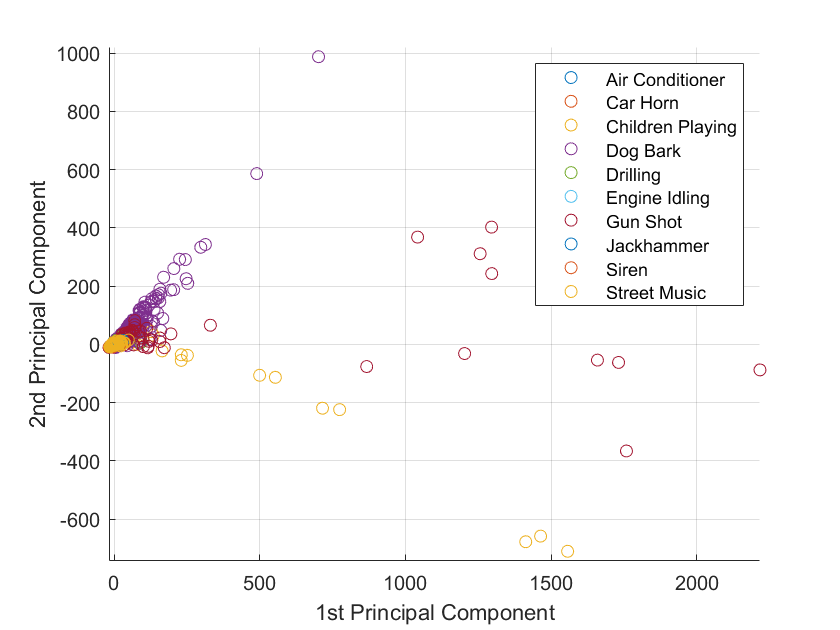

Data_Class = categorical(["Air Conditioner","Car Horn","Children Playing","Dog Bark","Drilling","Engine Idling","Gun Shot","Jackhammer","Siren","Street Music"]);
figure()
for i =1:1:length(categories(FeatureTable1.Label))
scatter(score(FeatureTable1{:,14}==Data_Class(i),1),score(FeatureTable1{:,14}==Data_Class(i),2))
hold on
axis equal
end
legend(Data_Class)
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
grid on

Observation : In PCA, it stated that the first 2 principal components represent >99% of data, theoretically, we could transform the features into 2 PCA components for machine learning training, however, we will lost "power" to explain how the features impact on the accuracy of model. If we are looking at the graph, many classes does not have significant distinction, we might dont have good accuracy result if we only use time-domain and spectral features to train machine learning model.

head(FeatureTable1)

ans = 8×14 table
    Signal_stats_Col1_ShapeFactor    Signal_stats_Col1_Kurtosis    Signal_stats_Col1_ClearanceFactor    Signal_stats_Col1_ImpulseFactor    Signal_stats_Col1_CrestFactor    Signal_stats_Col1_PeakValue    Signal_stats_Col1_SNR    Signal_stats_Col1_SINAD    Signal_ps_spec_Col1_BandPower    Signal_stats_Col1_Std    Signal_stats_Col1_RMS    Signal_ps_spec_Col1_PeakFreq1    Signal_ps_spec_Col1_PeakAmp1         Label     
    _____________________________    __________________________    _________________________________    _______________________________    _____________________________    ___________________________    _____________

Notice that the features are not on the same scale. This will bias the classifier. Normalize the features by subtracting the mean and dividing the standard deviation of each column.

FeatureTable1{:,1:13} = normalize(FeatureTable1{:,1:13},'range');
head((FeatureTable1))

ans = 8×14 table
    Signal_stats_Col1_ShapeFactor    Signal_stats_Col1_Kurtosis    Signal_stats_Col1_ClearanceFactor    Signal_stats_Col1_ImpulseFactor    Signal_stats_Col1_CrestFactor    Signal_stats_Col1_PeakValue    Signal_stats_Col1_SNR    Signal_stats_Col1_SINAD    Signal_ps_spec_Col1_BandPower    Signal_stats_Col1_Std    Signal_stats_Col1_RMS    Signal_ps_spec_Col1_PeakFreq1    Signal_ps_spec_Col1_PeakAmp1         Label     
    _____________________________    __________________________    _________________________________    _______________________________    _____________________________    ___________________________    _____________

## **Split the dataset**

Create cross-validation partition for data

In data science, usually we will split data into 3 parts : Trainining, Validation and Testing.

In regression learner designer, it will help to split into Training and Validation, therefore, now we split the testing dataset out first.

rng(1)
cvp = cvpartition(FeatureTable1.Label,'HoldOut',0.7)

cvp = Hold-out cross validation partition
   NumObservations: 8732
       NumTestSets: 1
         TrainSize: 2620
          TestSize: 6112

dataTrain_Validation = FeatureTable1(cvp.training,:);
dataTest = FeatureTable1(cvp.test,:);